%--- Filtro di Kalman e Loop Transfer Recovery ---
% sistema massa-molla-smorzatore

% parametri
m = 10; c = -0.5; k = 2; %m=massa, c=coef. di attrito, k=cost. elastica

A = [0 1; -k/m -c/m];
B = [0; 1/m];
C = [1 0];
D = 0;

sys = ss(A, B, C, D);
sys_tf = tf(sys); % fdt

display(sys);


sys =
 
  A = 
         x1    x2
   x1     0     1
   x2  -0.2  0.05
 
  B = 
        u1
   x1    0
   x2  0.1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


display(sys_tf);


sys_tf =
 
         0.1
  ------------------
  s^2 - 0.05 s + 0.2
 
Continuous-time transfer function.


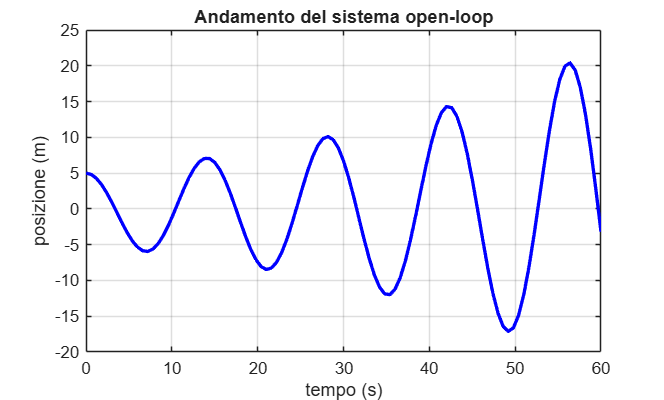


% simulazione open-loop
x0 = [5; 0]; 
t_finale = 60;
[y, t] = initial(sys, x0, t_finale);

figure;
% plot della Posizione (x1 / y)
plot(t, y, 'b', 'LineWidth', 2);
ylabel('posizione (m)');
xlabel('tempo (s)');
title('Andamento del sistema open-loop');
grid on;


Q = diag([1/10 1/8]); %Q è n x n
display(Q);

Q =     0.1000         0
         0    0.1250



R = 1/5; % R è m x m (ho solo un ingresso u1 -> scalare)
display(R);

R = 0.2000


Gamma = sys.B;

q = 1e4; % parametro di progetto
W = 1 + q; % W_0 = 1
V = 1;

% guadagno LQR (identico) (ma con un unico comando)
K_c = lqr(sys, Q, R); % N = 0;
% guadagno dell'osservatore
K_f = lqe(sys.A, Gamma, C, W, V); % risolve la A.R.E. duale

display(K_c);

K_c =     0.1213    2.3170


disp('Nota: il guadagno K_c è lo stesso.');

Nota: il guadagno K_c è lo stesso.


display(K_f);

K_f =     4.4780
   10.0264



K = ss(sys.A-(K_f*sys.C)-(sys.B*K_c), K_f, -K_c, 0) % compensatore K(s)


K =
 
  A = 
            x1       x2
   x1   -4.478        1
   x2   -10.24  -0.1817
 
  B = 
          u1
   x1  4.478
   x2  10.03
 
  C = 
            x1       x2
   y1  -0.1213   -2.317
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


Ks = tf(K);
display(Ks);


Ks =
 
   -23.77 s + 0.8859
  --------------------
  s^2 + 4.66 s + 11.05
 
Continuous-time transfer function.



% funzione d'anello L(s)
L = Ks * sys_tf;
L_min = minreal(L);
display(L_min);


L_min =
 
               -2.377 s + 0.08859
  --------------------------------------------
  s^4 + 4.61 s^3 + 11.02 s^2 + 0.3793 s + 2.21
 
Continuous-time transfer function.



H = tf(ss(sys.A, sys.B, K_c, 0)); % funzione d'anello LQR

% verifico che non ci siano parti non ragg. o non oss. instabili
display(pole(sys_tf));

   0.0250 + 0.4465i
   0.0250 - 0.4465i



display(pole(L_min));

  -2.3299 + 2.3715i
  -2.3299 - 2.3715i
   0.0250 + 0.4465i
   0.0250 - 0.4465i



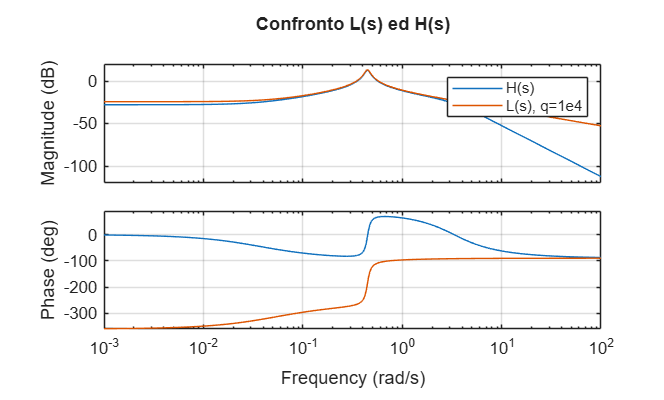


% al crescere di q, L(s) tende ad H(s)
figure;
bode(L_min, H);
title('Confronto L(s) ed H(s)');
legend('H(s)','L(s), q=1e4');
grid on;